# Forward Kinematics of the Stewart Platform


                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          7             1292.82                        3.58e+03              1
     1         14             41.8682              1             64.7              1
     2         21             30.1614            2.5             67.8            2.5
     3         28             11.5901           6.25             25.6           6.25
     4         35             1.29768        8.67922               72           15.6
     5         42         1.39519e-06       0.387038           0.0841           15.6
     6         49         7.50727e-16    0.000953124         2.06e-06           15.6
     7         56         1.61559e-27    1.03836e-08         1.96e-12           15.6

Equation solved.

fsolve completed because the vector of function values is n

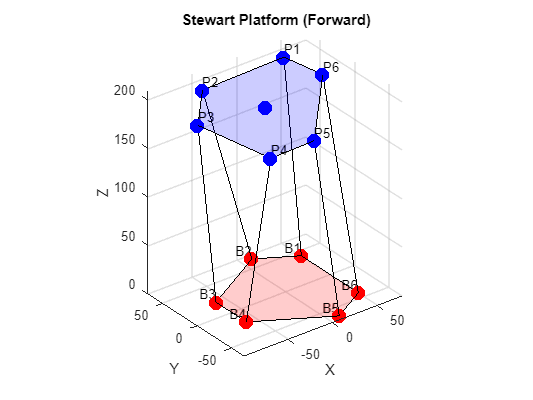

% x = stewart_forward_kinematics(out.B, out.P, out.leg_lengths);
% function [x] = stewart_forward_kinematics(B,P,leg_lengths)

x = stewart_forward_kinematics;


function [x] = stewart_forward_kinematics()
     
    R1=130/2; %radious of the base frame
    R2=125/2; %radious of the moving frame
    GAMMA=20; % half angle between to adjacent legs
    
    
    % Define the coordinates of the attachment points in the base and platform frames
    % Fixed platform attachment points (in the base frame)
    B1=[R1*cosd(60-GAMMA) R1*sind(60-GAMMA) 0]'; 
    B2=[R1*cosd(60+GAMMA) R1*sind(60+GAMMA) 0]'; 
    B3=[-R1*cosd(GAMMA) R1*sind(GAMMA) 0]'; 
    B4=[-R1*cosd(GAMMA) -R1*sind(GAMMA) 0]'; 
    B5=[R1*cosd(60+GAMMA) -R1*sind(60+GAMMA) 0]'; 
    B6=[R1*cosd(60-GAMMA) -R1*sind(60-GAMMA) 0]'; 
    
    % B Base frame
    B = [B1 B2 B3 B4 B5 B6];
    
    % Moving platform attachment points (in the moving frame)
    P1=[R2*cosd(GAMMA) R2*sind(GAMMA) 0]';
    P2=[-R2*sind(30-GAMMA) R2*cosd(30-GAMMA) 0]';
    P3=[-R2*sind(30+GAMMA) R2*cosd(30+GAMMA) 0]';
    P4=[-R2*sind(30+GAMMA) -R2*cosd(30+GAMMA) 0]';
    P5=[-R2*sind(30-GAMMA) -R2*cosd(30-GAMMA) 0]';
    P6=[R2*cosd(GAMMA) -R2*sind(GAMMA) 0]';
    
    % P Platform frame
    P = [P1 P2 P3 P4 P5 P6];
    
    % leg_lengths is Lengths of the legs (Input)
    leg_lengths = [209.955064628481
199.763022854702
180.235381105315
173.779164091752
182.687665985851
210.639995724864];
    
    % Initial guess for platform position and orientation (x, y, z, roll, pitch, yaw)
    x0 = [0, 0, mean(leg_lengths), 0, 0, 0];
    
    % Solve for the position and orientation 
    % using fsolve (non linear solver)
    options = optimoptions('fsolve', 'Display', 'iter');
    % % options = optimoptions('fsolve','Display', 'none');

    %[x, fval, exitflag] = fsolve(@(x) kinematic_equations(x, B, P, leg_lengths), x0, options);
    x = fsolve(@(x) kinematic_equations(x, B, P, leg_lengths), x0, options);
    
    % % Round the x values to 4 digits
    % round_4 = @(value) round(value,4);
    % x = round_4(x);

    % Print the result on display
    fprintf('Position and orientation of the platform:\n');
    fprintf('x: %.4f\n', x(1));
    fprintf('y: %.4f\n', x(2));
    fprintf('z: %.4f\n', x(3));
    fprintf('roll: %.4f\n', rad2deg(x(4)));
    fprintf('pitch: %.4f\n', rad2deg(x(5)));
    fprintf('yaw: %.4f\n', rad2deg(x(6)));
    
    % Plot the Stewart platform in 3D
    [R, P_global, top_centre] = plot_stewart_platform(x, B, P);
end

# Functions

function F = kinematic_equations(x, B, P, leg_lengths)
    % Extract position and orientation from x
    px = x(1);
    py = x(2);
    pz = x(3);
    roll = x(4);
    pitch = x(5);
    yaw = x(6);
    
    % Rotation matrix from roll, pitch, yaw
        % R = eul2rotm([yaw, pitch, roll]); % Traditional method
    R = Eul2rotm([roll, pitch, yaw]);
    
    
    % Compute the equations for each leg
    F = zeros(6, 1);
    for i = 1:6
        % Platform attachment point in global frame
        p_global = [px; py; pz] + R * P(:, i);
        
        % Compute the distance between base and platform attachment points
        d = norm(p_global - B(:, i));
        
        % Equation for the leg length (
        % error (computed leg length - actual leg_length)
        F(i) = d - leg_lengths(i);
    end
    
end

% Traditional 
    % function R = eul2rotm(eul)
    %     % Convert Euler angles to rotation matrix
    %     % eul = [yaw, pitch, roll]
    %     yaw = eul(1);
    %     pitch = eul(2);
    %     roll = eul(3);
    % 
    %     % Rotation matrix around z-axis (yaw)
    %     Rz = [cos(yaw), -sin(yaw), 0;
    %           sin(yaw),  cos(yaw), 0;
    %           0,        0,       1];
    % 
    %     % Rotation matrix around y-axis (pitch)
    %     Ry = [cos(pitch), 0, sin(pitch);
    %           0,          1, 0;
    %           -sin(pitch), 0, cos(pitch)];
    % 
    %     % Rotation matrix around x-axis (roll)
    %     Rx = [1, 0,       0;
    %           0, cos(roll), -sin(roll);
    %           0, sin(roll),  cos(roll)];
    % 
    %     % Combined rotation matrix
    %     R = Rz * Ry * Rx;
    % end

function R = Eul2rotm(eul)
    % Assuming Euler angles are in the order of [roll, pitch, yaw]
    %%R = angle2dcm(eul(3), eul(2), eul(1));
    R = eul2rotm([eul(1), eul(2), eul(3)],"XYZ");

end

function [R, P_global, top_centre] = plot_stewart_platform(x, B, P)
    % Extract position and orientation
    px = x(1);
    py = x(2);
    pz = x(3);
    roll = x(4);
    pitch = x(5);
    yaw = x(6);
    
    % Rotation matrix from roll, pitch, yaw
    R = Eul2rotm([roll, pitch,yaw]);
    
    % Compute the platform attachment points in the global frame
    P_global = [px; py; pz] + R * P;
    
    % Plot the base attachment points
    figure;
    hold on;
    plot3(B(1,:), B(2,:), B(3,:), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
    hold on
    fill3(B(1,:), B(2,:), B(3,:),'r', 'FaceAlpha', 0.2);
    text(B(1,:), B(2,:), B(3,:), {'B1', 'B2', 'B3', 'B4', 'B5', 'B6'}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');

    % Plot the platform attachment points
    plot3(P_global(1,:), P_global(2,:), P_global(3,:), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
    hold on
    fill3(P_global(1,:), P_global(2,:), P_global(3,:),'b','FaceAlpha', 0.2);
    text(P_global(1,:), P_global(2,:), P_global(3,:), {'P1', 'P2', 'P3', 'P4', 'P5', 'P6'}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');

    % Plot the legs
    for i = 1:6
        plot3([B(1,i), P_global(1,i)], [B(2,i), P_global(2,i)], [B(3,i), P_global(3,i)], 'k-');
    end

    %Plot Centre
    top_centre = mean(P_global,2);
    plot3(top_centre(1),top_centre(2),top_centre(3),'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
    
    
    % Plot settings
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    title('Stewart Platform (Forward)');
    grid on;
    axis equal;
    view(3);
    hold off;
end